Change the temperature here according to your heart's desire

% open the googP_logits.mat file from get_logits folder

introduce_functions;
temperature = 1;
dataSetName = "DinoV2";



logits = dino_logits(1:9999,:);
Y_logit = dino_logits(10000,:);

smData = soft_max(logits,temperature);
smYData = soft_max(Y_logit,temperature);

this does one-to-many distances

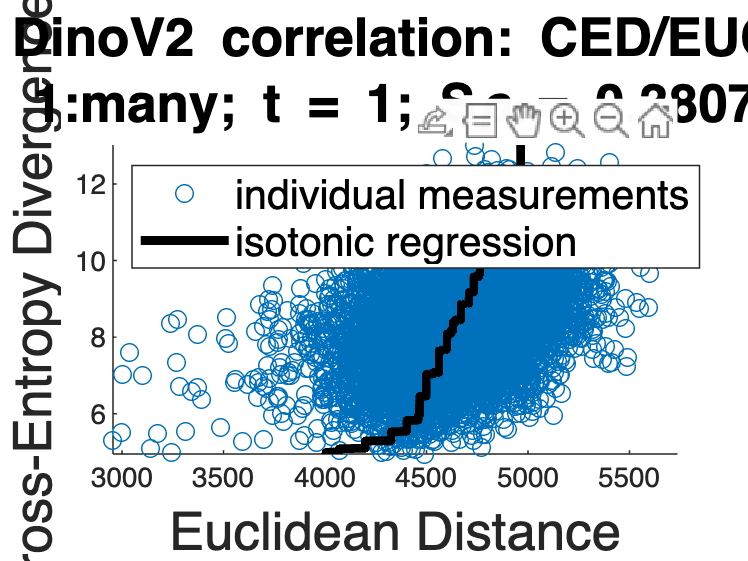


dists1 = CED(smYData,smData);
dists2 = EUC(Y_logit,logits);

chart_title1 = strcat(dataSetName," correlation: CED/EUC");
chart_title2 = strcat("1:many; ","t = ",num2str(temperature));
chart_title = [chart_title1,chart_title2];

shepard_spear(dists1,dists2,chart_title,"Euclidean Distance","Cross-Entropy Divergence");

and this does many-to-many tests

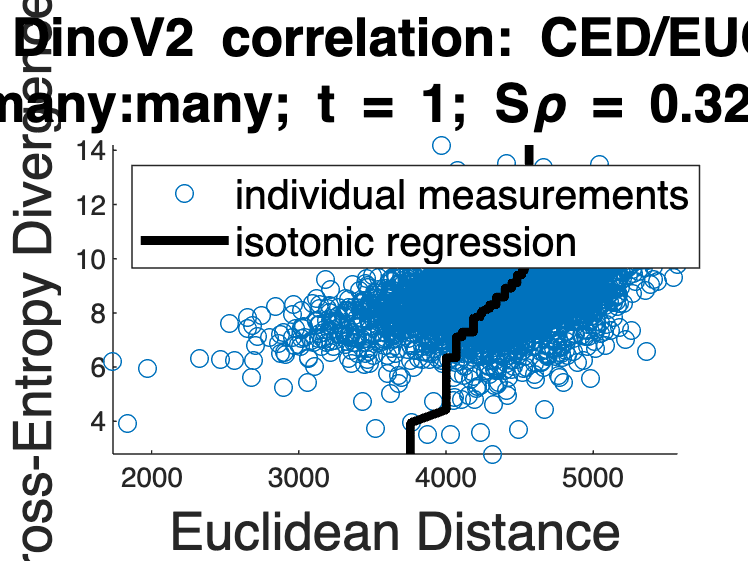


dists1 = pdist(smData(1:100,:),CED);
dists2 = pdist(logits(1:100,:),EUC);

chart_title1 = strcat(dataSetName," correlation: CED/EUC");
chart_title2 = strcat("many:many; ","t = ",num2str(temperature));
chart_title = [chart_title1,chart_title2];

shepard_spear(dists1,dists2,chart_title,"Euclidean Distance","Cross-Entropy Divergence");